# Exercise 8.1 - Generating a musical chord

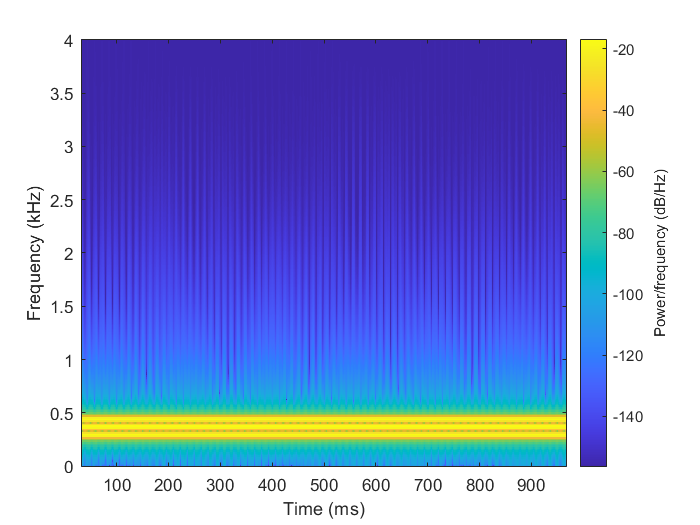

% Chord note frequencies
fd4 = 293.66;
ffsharp4 = 369.99;
fa4 = 440;

% Sampling frequency and discrete time vector
fs = 8000;
n = 0 : fs - 1;

% Chord waves
x1 = cos(2 * pi * fd4 / fs * n);
x2 = cos(2 * pi * ffsharp4 / fs * n);
x3 = cos(2 * pi * fa4 / fs * n);

% First harmonic waves
x1_1 = cos(2 * pi * 2 * fd4 / fs * n);
x2_1 = cos(2 * pi * 2 * ffsharp4 / fs * n);
x3_1 = cos(2 * pi * 2 * fa4 / fs * n);

% Adding up chord frequencies + first harmonic frequencies
chord = x1 + x2 + x3;
first_harmonic = x1_1 + x2_1 + x3_1;
chord_harmonic = chord + 0.5 * first_harmonic;

% Plot spectrograms (with and without harmonics)
spectrogram(chord, hanning(512), 500, 512, fs, 'yaxis');

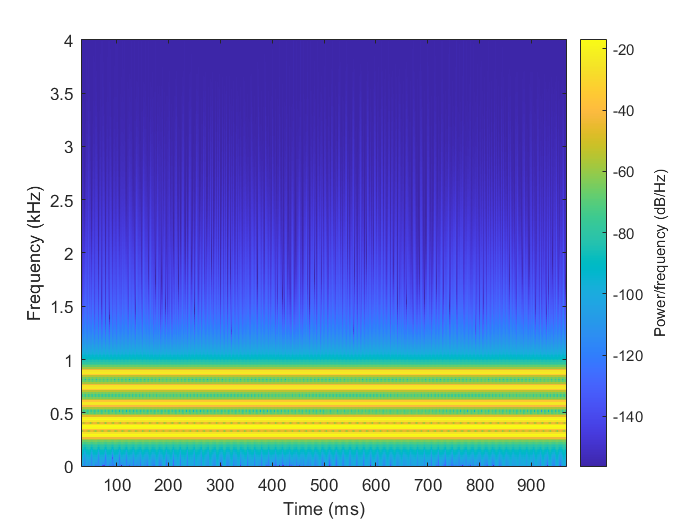

spectrogram(chord_harmonic, hanning(512), 500, 512, fs, 'yaxis');


% Play and export the resulting signal
soundsc(chord_harmonic);
audiowrite('audio\chord.wav', 0.2 * chord_harmonic, fs);    